# Neville’s Iterated Interpolation

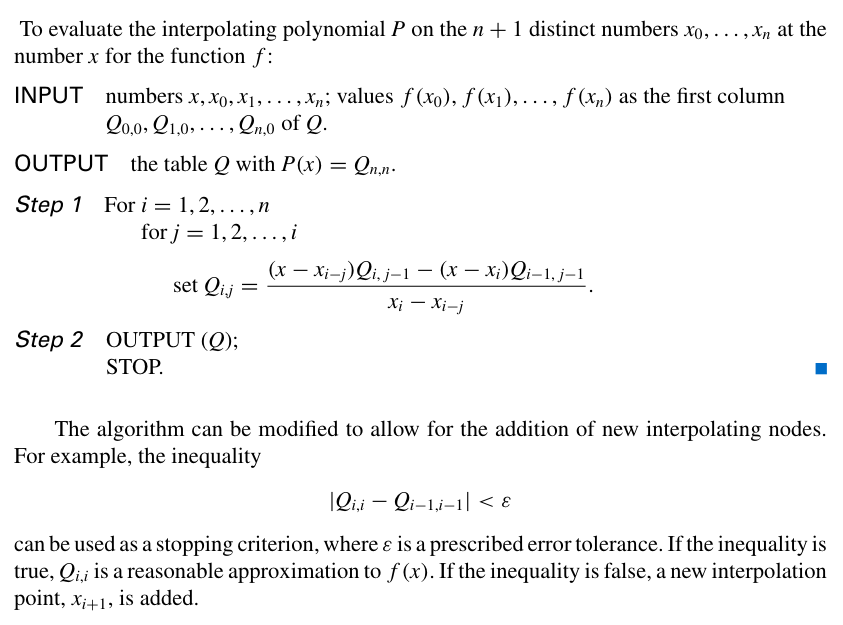

Clear Previous Data

clc;
clear;

Input the initial point:

X = [1.0 1.3 1.6 1.9]; % Initial Value
xvalue=1.5;            % Approximation Value
n = size(X);
n = n(2);
Y=[];
for i = 1:n
    Y(i)=func(X(i));   %Exact value for Y
end

## Iteration Rule

Start build the interated Interpolation:


$$Q_{i, j}=\frac{\left(x-x_{i-j}\right) Q_{i, j-1}-\left(x-x_{i}\right) Q_{i-1, j-1}}{x_{i}-x_{i-j}}$$


for i = 1:n
    Q(i,1)=Y(i); %Input the value in Q(i+1,0+1)
end

for i=2:n
    for j=2:i
        Q(i,j)=((xvalue-X(i-j+1))*Q(i,j-1)-(xvalue-X(i))*Q(i-1,j-1))/(X(i)-X(i-j+1));
    end
end

    1.0000         0         0         0
    1.6900    2.1500         0         0
    2.5600    2.2700    2.2500         0
    3.6100    2.2100    2.2500    2.2500



## �Appendix Function

function y = func(x)
    y=x^2;
end